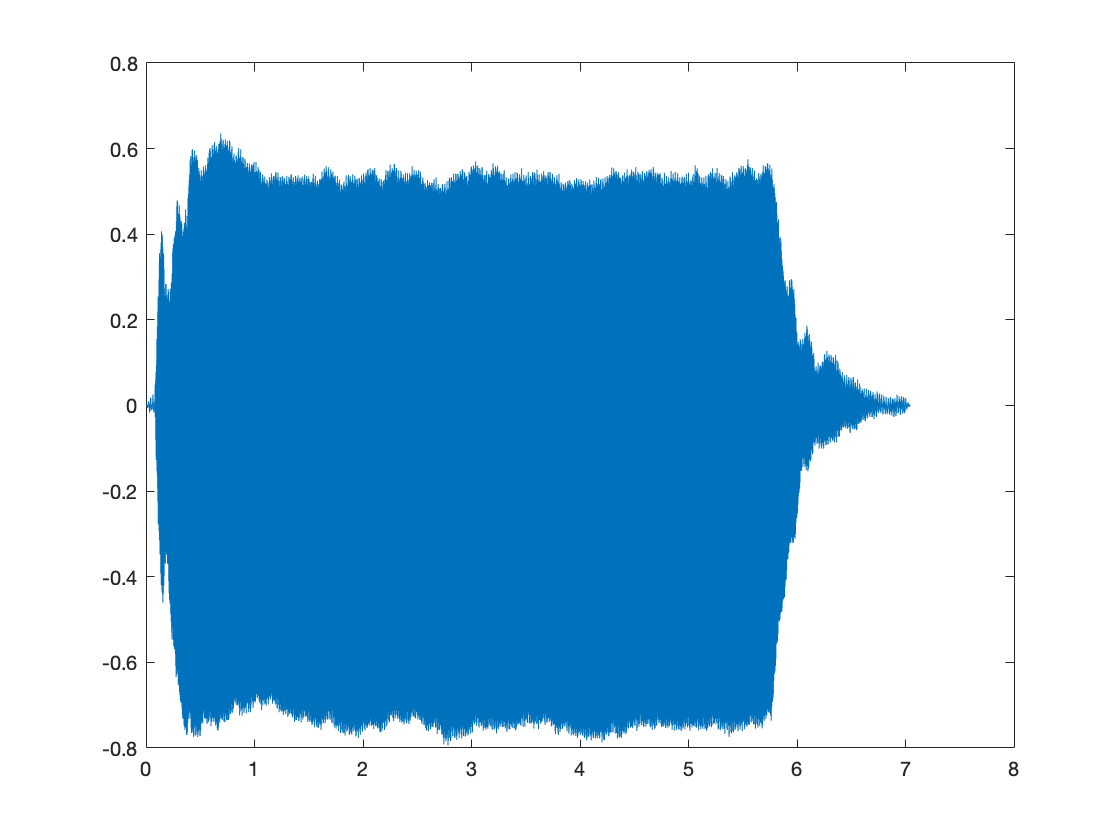

filename = 'organ-C3.wav';
[x,Fs] = audioread(filename);
Ts = 1/Fs;                  % Sampling period
L = length(x);              % Length of signal
t = [0:length(x)-1] * Ts;   % Time vector
%sound(x,Fs);

plot(t, x)

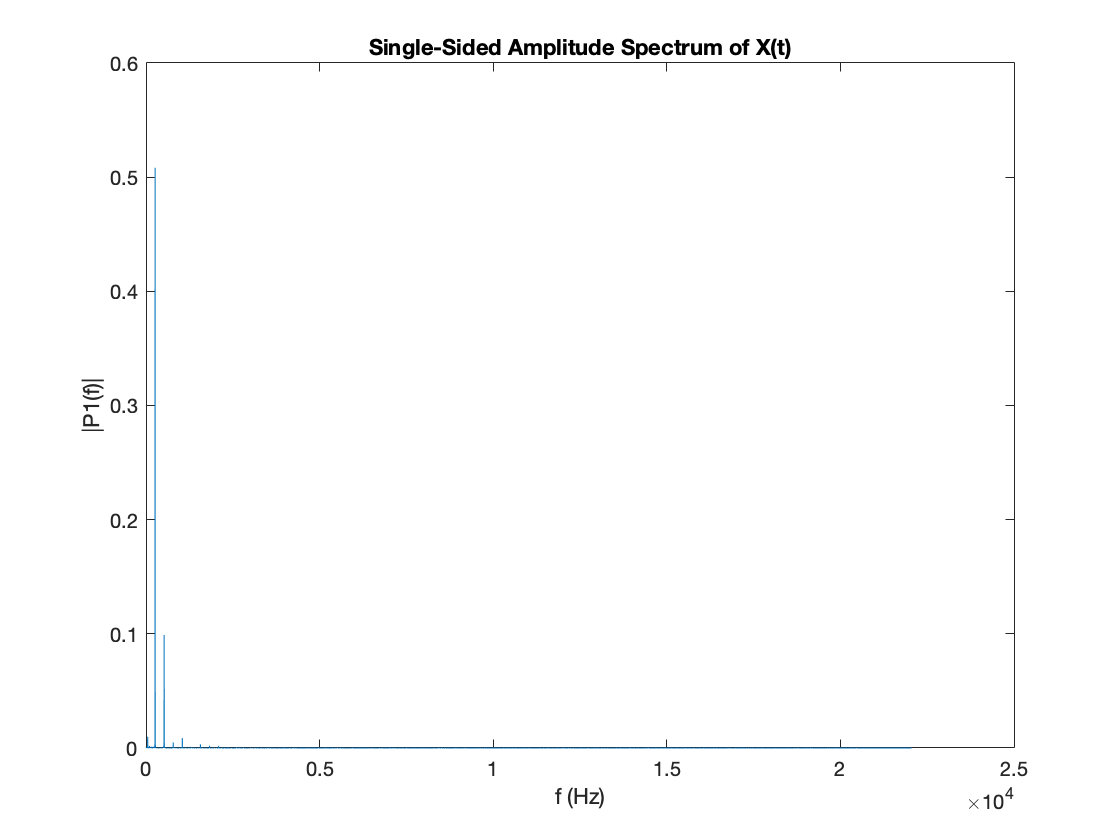

Y = fft(x);

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

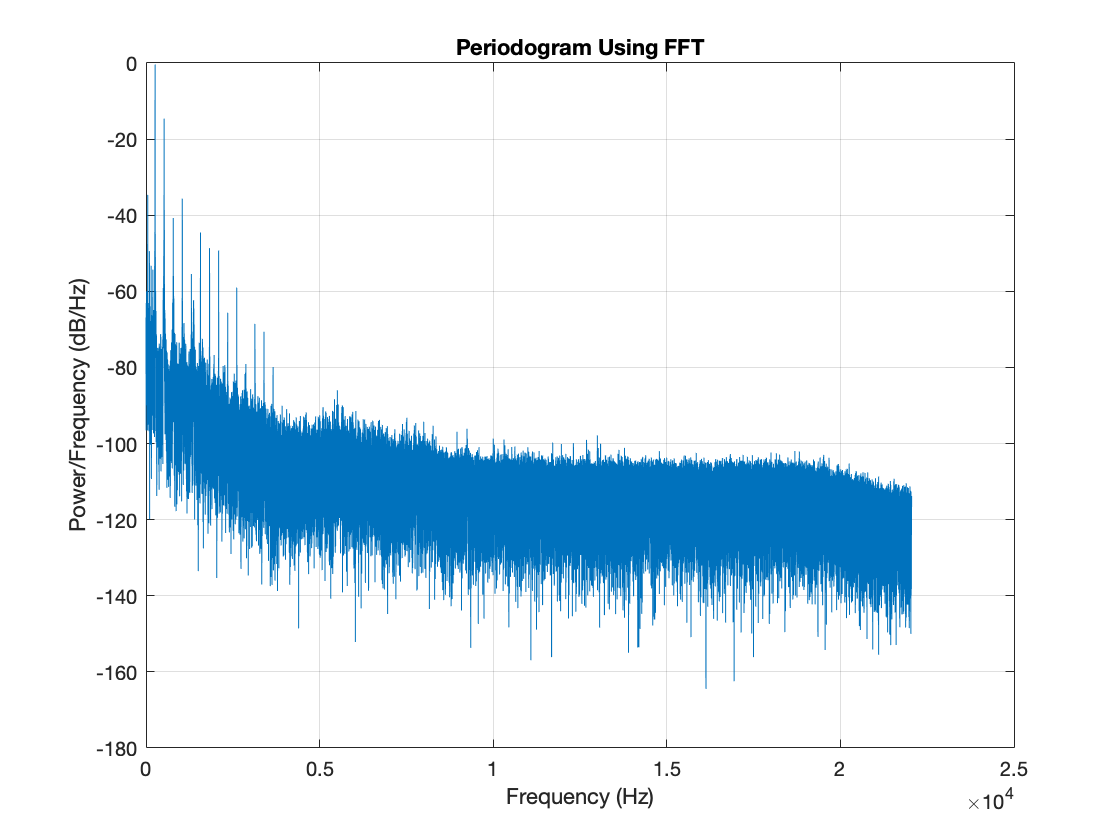

xdft = fft(x);
xdft = xdft(1:L/2+1);
psdx = (1/(Fs*L)) * abs(xdft).^2;
psdx(2:end-1) = 2*psdx(2:end-1);
freq = 0:Fs/L:Fs/2;

plot(freq,10*log10(psdx))
grid on
title('Periodogram Using FFT')
xlabel('Frequency (Hz)')
ylabel('Power/Frequency (dB/Hz)')

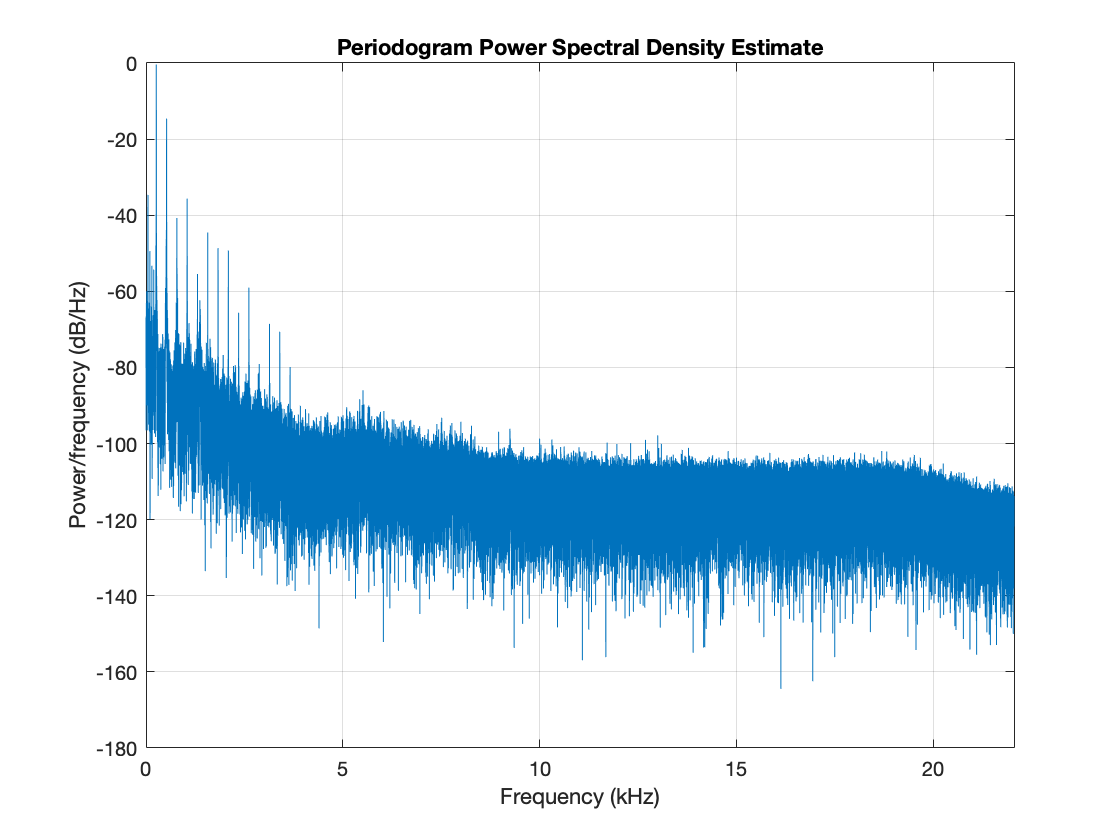

periodogram(x,rectwin(L),L,Fs)

S = (gnegate(sin(2*pi*261*t)))';
signal = x+S;
%sound(signal,Fs);